# Practical 3 - reverse correlation

Using spiketimes-revcorr.1.mat.

## Part I: Visualising the stimulus

cd('/MATLAB Drive/CompCourse/Practical 3')
data = load('spiketimes-revcorr.1.mat')

data = struct with fields:
     spiketimes: {[1x1209 double]  [1x1038 double]  [1x1018 double]  [1x995 double]  [1x977 double]  [1x1061 double]  [1x1033 double]}
    stimulus_ft: [34x5000 double]


**Q1. What variables does the file contain? What kind of variables are they? How big are they?**

**A:** It's a struct containing the 1x1209 cell array `spiketimes` and the 34x5000 double array `stimulus_ft`. 

**Q2. How long is the stimulus, in samples?**

nSamples = size(data.stimulus_ft,2)

nSamples = 5000

**A:** The stimulus is sampled 5000 times at each frequency.

lastSampleTime = (6.25*(nSamples-1));
t = 0:6.25:lastSampleTime; %samples last 6.25 ms

f=logspace(log10(500),log10(22400),34);

**Q3. What does logspace do?**

**A:** Generates an array of logarithmically spaced points between the first two inputs ( log10(500) and log10(22400) ) with length equal to the third input (n=34).

**Q4. Put the resulting figure in your Word doc. Describe the stimulus in a couple of sentences: do you think it is a natural or synthetic sound? What aspect of it is random? What aspect is systematic?**

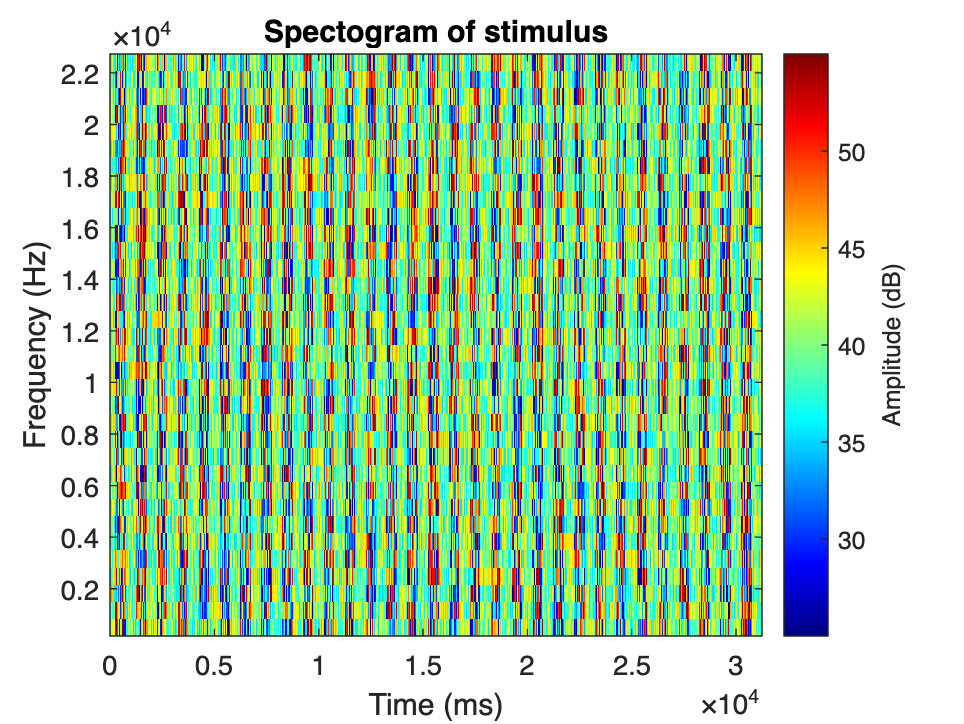

imageX = [t(1),t(end)];
imageY = [f(1),f(end)];

imagesc(imageX,imageY,data.stimulus_ft);
colormap(jet);
a = colorbar;
a.Label.String = 'Amplitude (dB)';
axis xy
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('Spectogram of stimulus')

**A**: It seems like synthetic noise (across all frequencies) being presented in alternating high (~50db) and low (~30db) amplitude intervals. 

## *Part II: Visualising the neuronal response*

*a*

**Q5. How many times was the stimulus repeated? How many spikes were recorded on each of the first two presentations? Why does spiketimes need to be a cell array, rather than a normal array?**

nTrials = size(data.spiketimes,2)

nTrials = 7

**A: **There are 7 trials, and in the first one, 1209 spikes were recorded, in the second one 1038 spikes were recorded. The cell array allows us to collate different-sized arrays into a single indexable array - this is necessary because the number of spikes varies from trial to trial.

**Q6. Label the axes and paste into your Word doc.**

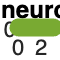

%Raster plot (again...)
close all;
sz = size(data.spiketimes{1},2);
single_trial = data.spiketimes{1};
figure;
scatter(single_trial,ones(sz), 'o','MarkerEdgeAlpha',0.2);
title('Single trial neuron rasterplot')
xlabel('Time (ms)')

**Q7. What does ‘hold on’ do? How do you turn it off again?**

**A**: This will let the next figure or plot be inserted into the current figure window. With a subplot function, it allows us to have multiple axes in one window. We turn it off with `hold off`.

**Q8. Label the raster and put it into your Word doc. Can you interpret it? If not, what aspects of the neuronal response, or the experiment, are preventing you?**

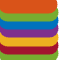

plotraster;

**A**: Somewhat interpretable, to the extent that it suggests that the neuron is tonically firing since the stimulus is likely synthetic (random) noise. That said, it seems less interpretable because the sampling rate is very high.

**Q9. Label the PSTH and put it into your Word doc. Does the PSTH help you interpret the neuronal response? Compare the response to the stimulus. Can you say anything about the relationship between the stimulus and the response? If not, why not?**

allspiketimes = [data.spiketimes{:}];

binStep = 6.25; %step in ms
binEnd = binStep*round(32000/binStep); %make sure it's integer

response = histc(allspiketimes,t);
response = response/(binStep/1000); %rescale to Hz
meanResponse = (response/nTrials);


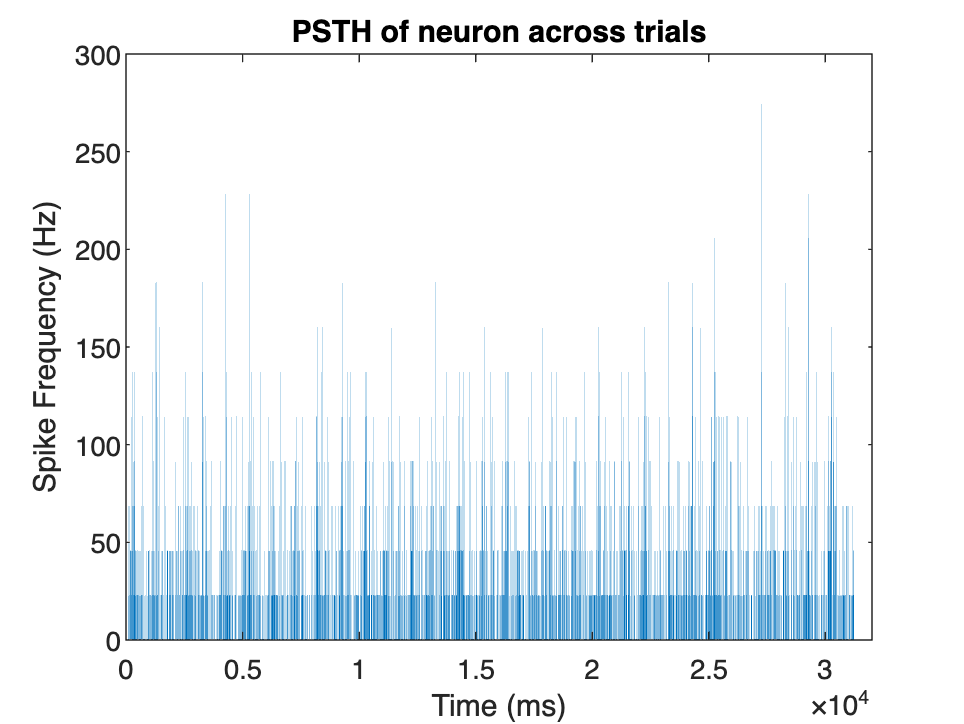

bar(binEdges,meanResponse)
xlabel('Time (ms)')
ylabel('Spike Frequency (Hz)')
title('PSTH of neuron across trials')

**A:** It does seem to help a bit, however the outcome will depend on the bin size. The neuronal response seems constant (with slight random variation) in response to the stimulus.

## *Part III: Reverse correlation*

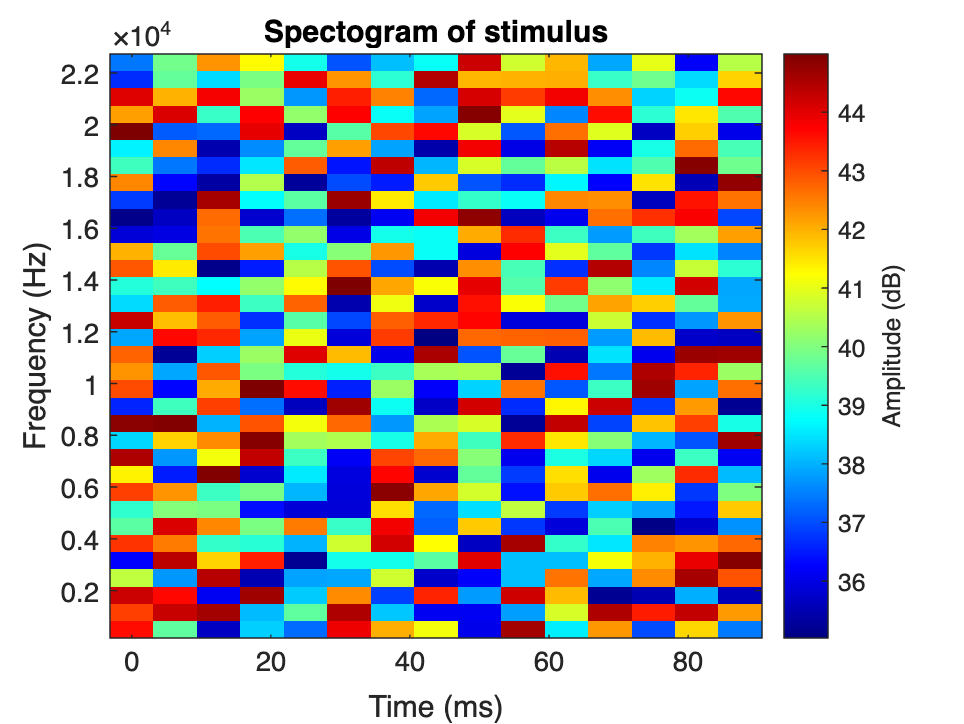

sta = zeros(size(data.stimulus_ft,1),15);
tm = allspiketimes(1);
col = ceil(tm/6.25);
sta = sta + data.stimulus_ft(:,[col-15:col-1]);


imagesc([t(1),t(col-1)], [f(1),f(end)], sta)
colormap(jet);
a = colorbar;
a.Label.String = 'Amplitude (dB)';
axis xy
xlabel('Time (ms)')
ylabel('Frequency (Hz)')
title('Spectogram of stimulus')

**Q10. While the program runs, you’ll see the figure changing, first rapidly, and later more slowly. What is happening? What does the figure look like to begin with? What does it end up as?**

**Q11. Once the program has run completely, label the final figure and paste it into your Word doc. What does the STA tell you about the relationship between stimulus and response? What’s the frequency tuning of the neuron? What’s its response latency in ms?**

sta =    40.0016   39.8022   39.9833   39.8674   39.8782   39.8940   39.8872   40.0254   39.8408   39.9764   39.7799   39.9373   39.9397   39.8257   39.9784
   39.9440   40.0261   39.9999   40.1606   40.0259   40.1155   40.0906   40.1067   40.0796   40.1189   40.1861   40.0653   40.1680   40.0800   39.9718
   39.8259   39.8622   39.9563   39.8559   39.8290   39.8337   40.0854   39.9862   39.8028   39.9457   40.0829   40.0251   39.9470   39.8850   39.8199
   40.2937   40.1863   40.0656   40.2940   40.1414   40.0752   40.1669   40.4035   40.3380   40.3130   40.3991   40.2257   40.2745   40.2909   40.2954
   40.0605   40.1321   40.0412   39.9859   40.0351   40.0360   39.9507   39.9478   40.0096   39.9613   40.1237   39.8921   40.0979   40.0275   40.0082
   39.9072   40.0624   40.2391   39.9699   39.8907   39.9943   39.8441   40.0978   39.9786   40.2049   39.9632   40.1209   39.9195   39.9727   39.9734
   39.9519   39.9882   39.8988   40.1195   39.9641   40.0284   40.0426   40.0215   39.92

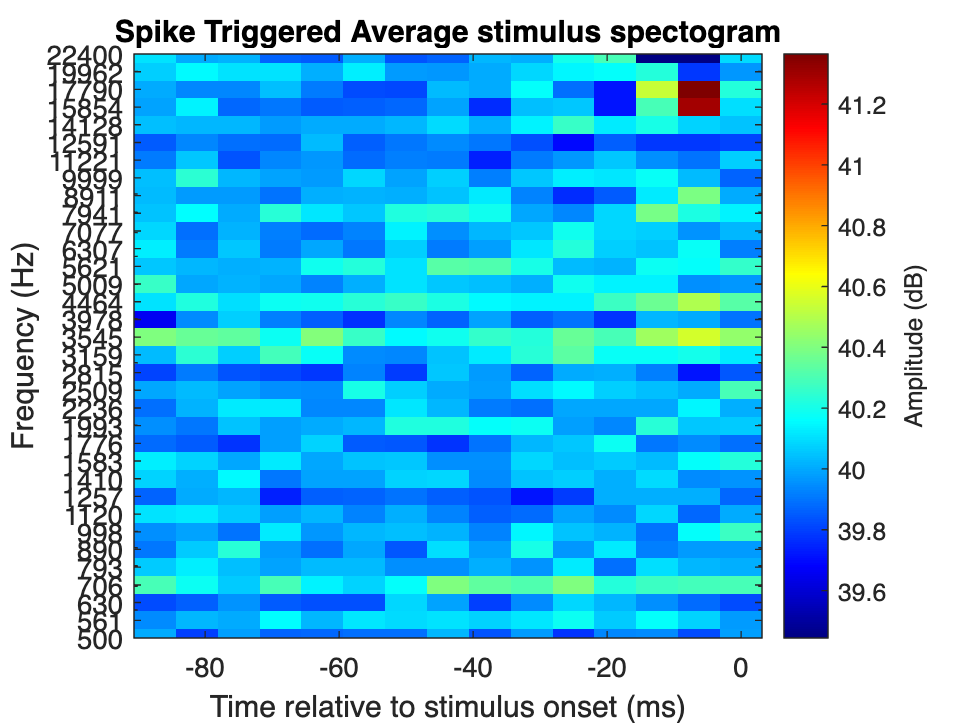

getsta

**Q12. Put the labelled separable kernel plot into your word doc. How do the separable kernel and the STA compare? Which is more informative? Why?**

out = separablekernel(data.stimulus_ft,histc(allspiketimes,t),15)

out =    -0.0001   -0.0001    0.0001   -0.0002   -0.0000    0.0002    0.0001   -0.0001    0.0002   -0.0001    0.0002    0.0007   -0.0010   -0.0028   -0.0002
    0.0001    0.0002   -0.0001    0.0002    0.0000   -0.0002   -0.0001    0.0001   -0.0002    0.0001   -0.0002   -0.0008    0.0011    0.0031    0.0002
   -0.0001   -0.0001    0.0001   -0.0002   -0.0000    0.0002    0.0001   -0.0001    0.0002   -0.0001    0.0002    0.0008   -0.0010   -0.0028   -0.0002
    0.0001    0.0003   -0.0002    0.0003    0.0001   -0.0004   -0.0002    0.0002   -0.0003    0.0002   -0.0004   -0.0014    0.0018    0.0051    0.0004
    0.0000    0.0001   -0.0001    0.0001    0.0000   -0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001   -0.0004    0.0005    0.0015    0.0001
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0001    0.0002   -0.0003   -0.0008   -0.0001
    0.0001    0.0002   -0.0002    0.0003    0.0001   -0.0004   -0.0002    0.0002   -0.00

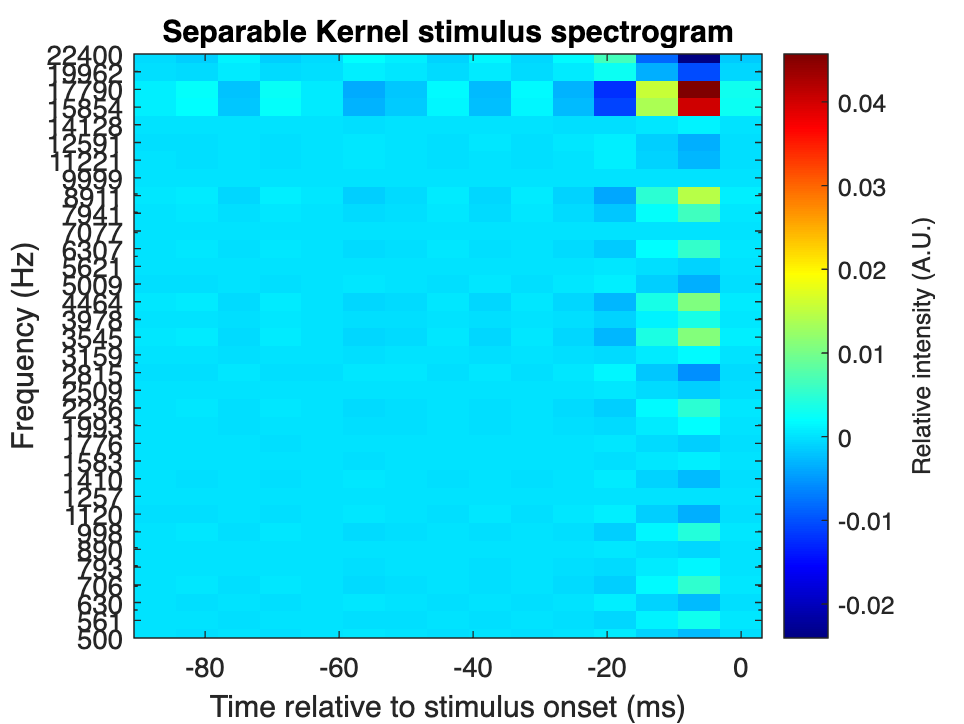


imagesc([-14*6.25,0], [f(1),f(end)], out)
set(gca, 'Yscale','log','Ylim',[f(1),f(end)],'YTick',round(f))
axis xy
colormap(jet);
a = colorbar;
a.Label.String = 'Relative intensity (A.U.)';
xlabel('Time relative to stimulus onset (ms)')
ylabel('Frequency (Hz)')
title('Separable Kernel stimulus spectrogram')